# Exploring the vocal beahvior of bats in the operant box

## First calculating inter-call intervals and explore the distribution

fprintf(1,'*** Gathering Data for timing of vocal activity ***\n')

*** Gathering Data for timing of vocal activity ***


% BasePath = '/Volumes/server_home/users/JulieE/LMC';
BasePath = '/Volumes/JulieE8T'

BasePath = '/Volumes/JulieE8T'

TimeVocData = cell(10^3,1); % initialize the list to 1000
InterCallInterval = cell(1,10^3);
ExpFolders = dir(fullfile(BasePath,'LMC_*'));
NDays = 0; % counter for single days
for ee=1:length(ExpFolders)
    fprintf(1, '\n  -> Looking into  %s...\n ', fullfile(ExpFolders(ee).folder,ExpFolders(ee).name))
    DateFolders = dir(fullfile(ExpFolders(ee).folder,ExpFolders(ee).name, 'logger','20*'));
    for dd=1:length(DateFolders)
        fprintf(1, '   %s\n', DateFolders(dd).name);
        AllVocDataFiles = dir(fullfile(DateFolders(dd).folder, DateFolders(dd).name,'*VocExtractData*.mat'));
        if isempty(AllVocDataFiles)
            AllVocDataFiles = dir(fullfile(DateFolders(dd).folder, DateFolders(dd).name,'*VocExtractData.mat'));
        end
        ParamFiles = dir(fullfile(ExpFolders(ee).folder,ExpFolders(ee).name, 'audio',DateFolders(dd).name, '*VocTrigger*param.txt'));
        IndTrueVocFiles = nan(length(AllVocDataFiles),1);
        for ff=1:length(AllVocDataFiles)
            if contains(AllVocDataFiles(ff).name, '_200')
                IndTrueVocFiles(ff)= 0;
            else
                for pp=1:length(ParamFiles)
                    IndTrueVocFiles(ff)= 0;
                    if contains(AllVocDataFiles(ff).name,ParamFiles(pp).name(6:16))
                        IndTrueVocFiles(ff)= 1;
                        break
                    end
                end
            end
        end
        VocDataFiles = AllVocDataFiles(logical(IndTrueVocFiles));
        if ~isempty(VocDataFiles)
            NDays=NDays+1;
            TimeVocData{NDays}=[];
            InterCallInterval{NDays} = [];
            for ff=1:length(VocDataFiles)
                load(fullfile(VocDataFiles(ff).folder,VocDataFiles(ff).name),'Voc_transc_time_refined');
                [~, I] = sort(Voc_transc_time_refined(:,1));
                TimeVocData{NDays} = [TimeVocData{NDays}; Voc_transc_time_refined(I,:)];
                Local =Voc_transc_time_refined(I,:);
                ICI_local = (Local(2:end,1)-Local(1:end-1,2));
                ICI_local(ICI_local<0) = [];% remove negative values that are due to the few times where the Listener bat vocalized in the set up
                InterCallInterval{NDays} = [InterCallInterval{NDays} ICI_local'];
                
                fprintf(1,'     %d calls\n', length(Voc_transc_time_refined(:,1)))
            end
        
        end
    end
end


  -> Looking into  /Volumes/JulieE8T/LMC_CoEd...
 

   20190506


     31 calls


   20190507


     6 calls
     11 calls


   20190508


     22 calls


   20190509
   20190510
   20190513


     117 calls


   20190514


     134 calls


   20190515


     156 calls


   20190516


     145 calls


   20190517
   20190520


     71 calls


   20190521


     82 calls


   20190522


     127 calls


   20190523
   20190524
   20190603


     1 calls


   20190604


     48 calls


   20190605


     82 calls


   20190606


     21 calls
     29 calls


   20190607


     53 calls


   20190610


     59 calls


   20190611


     91 calls


   20190612


     46 calls
     28 calls


   20190613


     97 calls


   20190614


     123 calls


   20190616


     79 calls


   20190617


     118 calls


   20190618


     74 calls


   20190619


     81 calls


   20190620


     118 calls


   20190621


     103 calls


   20190622


     73 calls


   20190623


     74 calls


   20190624


     62 calls


   20190625


     66 calls


   20190626


     77 calls


   20190627


     78 calls


   20190628


     81 calls


   20190629


     130 calls


   20190630


     65 calls


   20190701


     96 calls


   20190702


     110 calls


   20190703
   20190704


     83 calls


   20190705


     81 calls


   20190706


     67 calls


   20190707


     83 calls


   20190708


     84 calls


   20190709
   20190710


     71 calls


   20190711


     68 calls


   20190712


     51 calls



  -> Looking into  /Volumes/JulieE8T/LMC_HoHa...
 

   20190116


     10 calls
     6 calls
     6 calls
     39 calls


   20190117


     68 calls


   20190118


     2 calls
     100 calls
     13 calls


   20190119


     96 calls


   20190120


     100 calls
     35 calls


   20190122
   20190123


     100 calls
     9 calls


   20190124


     92 calls


   20190125


     83 calls


   20190129


     100 calls
     1 calls


   20190130


     100 calls
     83 calls


   20190131


     100 calls
     61 calls


   20190201


     100 calls
     80 calls


   20190202


     100 calls
     82 calls
     5 calls


   20190204


     100 calls
     81 calls


   20190205


     100 calls
     9 calls


   20190206


     100 calls
     36 calls


   20190207


     147 calls


   20190208


     96 calls


   20190212


     100 calls
     51 calls


   20190213


     125 calls


   20190214


     95 calls


TimeVocData = TimeVocData(1:NDays);
InterCallInterval = InterCallInterval(1:NDays);
fprintf(1, '\n Files from %d days of operant conditioning have been retrieved\n', NDays);


 Files from 66 days of operant conditioning have been retrieved


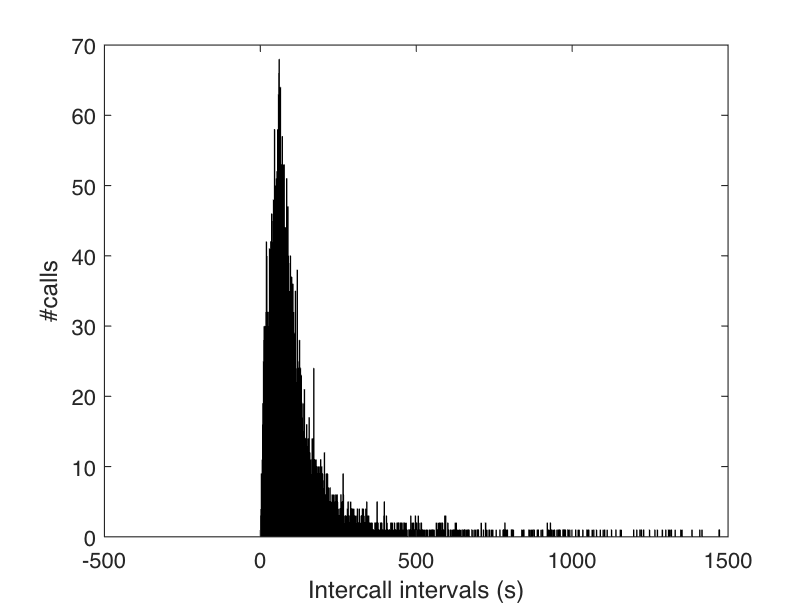

ICI = [InterCallInterval{:}]/10^3; % values in seconds
histogram(ICI,'BinWidth',1)
xlim([-500 1500])
xlabel('Intercall intervals (s)')
ylabel('#calls')

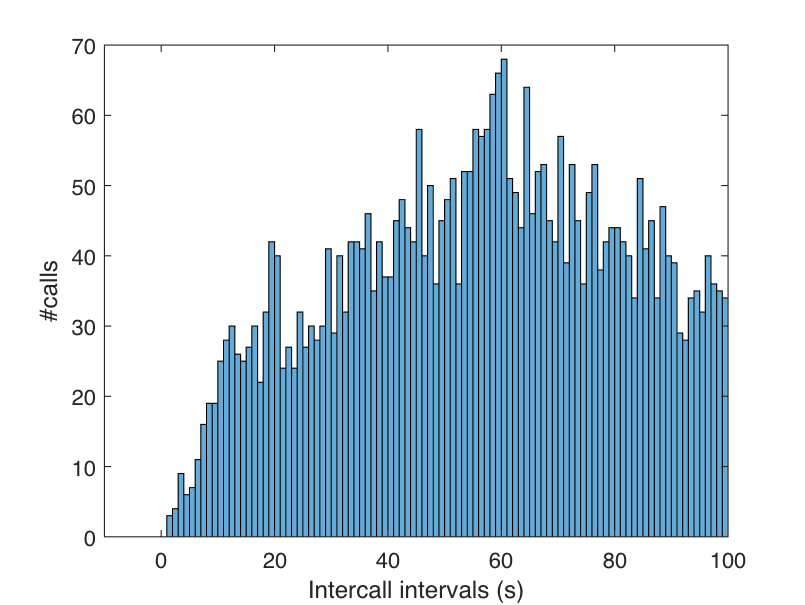

histogram(ICI,'BinWidth',1)
xlim([-10 100])
xlabel('Intercall intervals (s)')
ylabel('#calls')

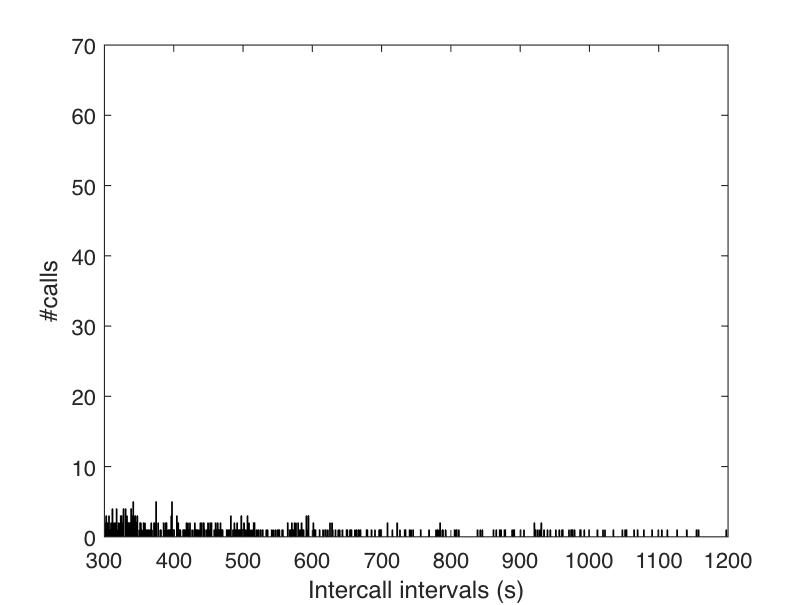

histogram(ICI,'BinWidth',1)
xlim([300 1200])
xlabel('Intercall intervals (s)')
ylabel('#calls')

nanmean(ICI)

ans = 131.0455

nanmedian(ICI)

ans = 81.0707

histogram(log2(ICI), 'BinWidth',1)
xlabel('#calls')
ylabel('log10 (Intercall Interval (s))')

## Explore the time to get the reward

fprintf(1,'*** Gathering Data for timing of reward ***\n')

*** Gathering Data for timing of reward ***


BasePath = '/Volumes/server_home/users/JulieE/LMC';
Time2Reward = cell(1,10^3); % initialize the list to 1000
Time2RewardFront = cell(1,10^3); % initialize the list to 1000
Time2RewardBack = cell(1,10^3); % initialize the list to 1000
Time2RewardBoth = cell(1,10^3); % initialize the list to 1000
ExpFolders = dir(fullfile(BasePath,'LMC_*'));
NDays = 0; % counter for single days
for ee=1:length(ExpFolders)
    fprintf(1, '\n  -> Looking into  %s...\n ', fullfile(ExpFolders(ee).folder,ExpFolders(ee).name))
    DateFolders = dir(fullfile(ExpFolders(ee).folder,ExpFolders(ee).name, 'audio','20*'));
    for dd=1:length(DateFolders)
        fprintf(1, '   %s\n', DateFolders(dd).name);
        DataFileStruc = dir(fullfile(DateFolders(dd).folder, DateFolders(dd).name, '*VocTrigger_events.txt'));
        if ~isempty(DataFileStruc)
            for exx=1:length(DataFileStruc)
                NDays=NDays+1;
                fprintf(1,'*** Getting events for that day ***\n');
                Fid_Data = fopen(fullfile(DataFileStruc(exx).folder,DataFileStruc(exx).name));
                EventsHeader = textscan(Fid_Data, '%s\t%s\t%s\t%s\t%s\t%s\t%s\n',1);
                for hh=1:length(EventsHeader)
                    if strfind(EventsHeader{hh}{1}, 'SampleStamp')
                        EventsStampCol = hh;
                    elseif strfind(EventsHeader{hh}{1}, 'Type')
                        EventsEventTypeCol = hh;
                    elseif strfind(EventsHeader{hh}{1}, 'FoodPortFront')
                        EventsFoodPortFrontCol = hh;
                    elseif strfind(EventsHeader{hh}{1}, 'FoodPortBack')
                        EventsFoodPortBackCol = hh;
                    elseif strfind(EventsHeader{hh}{1}, 'TimeStamp(s)')
                        EventsTimeCol = hh;
                    elseif strfind(EventsHeader{hh}{1}, 'Delay2Reward')
                        EventsRewardCol = hh;
                    end
                end
                Events = textscan(Fid_Data, '%s\t%f\t%s\t%s\t%f\t%f\t%f');
                fclose(Fid_Data);
                VocId = find(strcmp('Vocalization', Events{EventsEventTypeCol}));
                ReTriggerVocId = intersect(find(~isnan(Events{EventsRewardCol}) .* ~isinf(Events{EventsRewardCol})), VocId);
                ReTriggerVocFrontPId = intersect(find(~isnan(Events{EventsRewardCol}) .* (Events{EventsFoodPortFrontCol}==1) .* (Events{EventsFoodPortBackCol}==0)), VocId);
                ReTriggerVocBackPId = intersect(find(~isnan(Events{EventsRewardCol}) .* (Events{EventsFoodPortBackCol}==1) .* (Events{EventsFoodPortFrontCol}==0)), VocId);
                ReTriggerVocBothPId = intersect(find(~isnan(Events{EventsRewardCol}) .* (Events{EventsFoodPortBackCol}==1) .* (Events{EventsFoodPortFrontCol}==1)), VocId);
                Time2Reward{NDays} = Events{EventsRewardCol}(ReTriggerVocId)';
                Time2RewardFront{NDays} = Events{EventsRewardCol}(ReTriggerVocFrontPId)';
                Time2RewardBack{NDays} = Events{EventsRewardCol}(ReTriggerVocBackPId)';
                Time2RewardBoth{NDays} = Events{EventsRewardCol}(ReTriggerVocBothPId)';
                
            end
            
            
        end
    end
end


  -> Looking into  /Volumes/server_home/users/JulieE/LMC/LMC_CoEd...
 

   20190506


*** Getting events for that day ***


   20190507


*** Getting events for that day ***
*** Getting events for that day ***
*** Getting events for that day ***


   20190508


*** Getting events for that day ***


   20190509


*** Getting events for that day ***
*** Getting events for that day ***
*** Getting events for that day ***


   20190510


*** Getting events for that day ***


   20190513


*** Getting events for that day ***


   20190514


*** Getting events for that day ***


   20190515


*** Getting events for that day ***


   20190516


*** Getting events for that day ***


   20190517


*** Getting events for that day ***
*** Getting events for that day ***
*** Getting events for that day ***


   20190520


*** Getting events for that day ***


   20190521


*** Getting events for that day ***


   20190522


*** Getting events for that day ***


   20190523


*** Getting events for that day ***


   20190524


*** Getting events for that day ***


   20190603


*** Getting events for that day ***


   20190604


*** Getting events for that day ***


   20190605


*** Getting events for that day ***
*** Getting events for that day ***


   20190606


*** Getting events for that day ***
*** Getting events for that day ***
*** Getting events for that day ***


   20190607


*** Getting events for that day ***


   20190610


*** Getting events for that day ***


   20190611


*** Getting events for that day ***


   20190612


*** Getting events for that day ***
*** Getting events for that day ***


   20190613


*** Getting events for that day ***


   20190614


*** Getting events for that day ***


   20190616


*** Getting events for that day ***


   20190617


*** Getting events for that day ***


   20190618


*** Getting events for that day ***


   20190619


*** Getting events for that day ***


   20190620


*** Getting events for that day ***


   20190621


*** Getting events for that day ***


   20190622


*** Getting events for that day ***


   20190623


*** Getting events for that day ***


   20190624


*** Getting events for that day ***


   20190625


*** Getting events for that day ***


   20190626


*** Getting events for that day ***


   20190627


*** Getting events for that day ***


   20190628


*** Getting events for that day ***


   20190629


*** Getting events for that day ***


   20190630


*** Getting events for that day ***


   20190701


*** Getting events for that day ***
*** Getting events for that day ***


   20190702


*** Getting events for that day ***


   20190703


*** Getting events for that day ***


   20190704


*** Getting events for that day ***


   20190705


*** Getting events for that day ***


   20190706


*** Getting events for that day ***


   20190707


*** Getting events for that day ***


   20190708


*** Getting events for that day ***


   20190709


*** Getting events for that day ***


   20190710


*** Getting events for that day ***


   20190711


*** Getting events for that day ***


   20190712


*** Getting events for that day ***


   20200108


*** Getting events for that day ***


   20200109


*** Getting events for that day ***



  -> Looking into  /Volumes/server_home/users/JulieE/LMC/LMC_HoHa...
 

   20181210


*** Getting events for that day ***
*** Getting events for that day ***
*** Getting events for that day ***
*** Getting events for that day ***


   20181211


*** Getting events for that day ***


   20181212


*** Getting events for that day ***


   20181213


*** Getting events for that day ***
*** Getting events for that day ***


   20181214


*** Getting events for that day ***
*** Getting events for that day ***


   20181217


*** Getting events for that day ***
*** Getting events for that day ***


   20181218


*** Getting events for that day ***
*** Getting events for that day ***
*** Getting events for that day ***


   20181219


*** Getting events for that day ***


   20181220


*** Getting events for that day ***


   20181221


*** Getting events for that day ***


   20190108


*** Getting events for that day ***


   20190114


*** Getting events for that day ***
*** Getting events for that day ***
*** Getting events for that day ***
*** Getting events for that day ***
*** Getting events for that day ***


   20190115


*** Getting events for that day ***
*** Getting events for that day ***
*** Getting events for that day ***
*** Getting events for that day ***
*** Getting events for that day ***
*** Getting events for that day ***
*** Getting events for that day ***
*** Getting events for that day ***
*** Getting events for that day ***
*** Getting events for that day ***
*** Getting events for that day ***
*** Getting events for that day ***
*** Getting events for that day ***


   20190116


*** Getting events for that day ***
*** Getting events for that day ***
*** Getting events for that day ***
*** Getting events for that day ***


   20190117


*** Getting events for that day ***


   20190118


*** Getting events for that day ***
*** Getting events for that day ***


   20190119


*** Getting events for that day ***


   20190120


*** Getting events for that day ***


   20190122


*** Getting events for that day ***
*** Getting events for that day ***
*** Getting events for that day ***
*** Getting events for that day ***
*** Getting events for that day ***


   20190123


*** Getting events for that day ***


   20190124


*** Getting events for that day ***


   20190125


*** Getting events for that day ***


   20190128


*** Getting events for that day ***
*** Getting events for that day ***


   20190129


*** Getting events for that day ***


   20190130


*** Getting events for that day ***


   20190131


*** Getting events for that day ***


   20190201


*** Getting events for that day ***


   20190202


*** Getting events for that day ***


   20190203


*** Getting events for that day ***


   20190204


*** Getting events for that day ***


   20190205


*** Getting events for that day ***


   20190206


*** Getting events for that day ***


   20190207


*** Getting events for that day ***


   20190208


*** Getting events for that day ***


   20190211


*** Getting events for that day ***


   20190212


*** Getting events for that day ***


   20190213


*** Getting events for that day ***


   20190214


*** Getting events for that day ***


   20190401


*** Getting events for that day ***


Time2Reward = Time2Reward(1:NDays);
Time2RewardFront = Time2RewardFront(1:NDays);
Time2RewardBack = Time2RewardBack(1:NDays);
Time2RewardBoth = Time2RewardBoth(1:NDays);

T2R = [Time2Reward{:}];
histogram(T2R,'BinWidth',0.1)
xlabel('Time to reward (s)')
ylabel('#calls')


histogram(T2R*1000,'BinWidth',1)
xlim([0 100])
xlabel('Time to reward (ms)')
ylabel('#calls')


T2RF = [Time2RewardFront{:}];
histogram(T2RF,'BinWidth',0.1)
xlabel('Time to reward (s)')
ylabel('#calls')
title('Food port activated by Front bat (Ed)')


histogram(T2RF*1000,'BinWidth',1)
xlim([0 100])
xlabel('Time to reward (ms)')
ylabel('#calls')
title('Food port activated by Front bat (Ed)')


T2RB = [Time2RewardBack{:}];
histogram(T2RB,'BinWidth',0.1)
xlabel('Time to reward (s)')
ylabel('#calls')
title('Food port activated by Back bat (Co)')


histogram(T2RB*1000,'BinWidth',1)
xlim([0 100])
xlabel('Time to reward (ms)')
ylabel('#calls')
title('Food port activated by Back bat (Co)')


NumRe = cellfun(@length,Time2Reward);
NumReFr = cellfun(@length,Time2RewardFront);
NumReBa = cellfun(@length,Time2RewardBack);
NumReBoth = cellfun(@length,Time2RewardBoth);

plot([NumRe; NumReFr; NumReBa; NumReBoth]', 'LineWidth',2)
hold on
plot(NumReFr + NumReBa, 'r:', 'LineWidth',2)
hold off
legend({'All' 'Reward activated by Ed' 'Reward activated by Co' 'Reward activated by both' 'Sum Co Ed'})
ylabel('# rewarded calls')
xlabel('sessions')